clc;
clear;
syms y(x)
% 定义微分方程
Dy = diff(y,x) == y + 2*x;
% 使用dsolve求解
Y = dsolve(Dy, y(0) == 1);
disp(Y)

$$3\,{\mathrm{e}}^{x}-2\,x-2$$

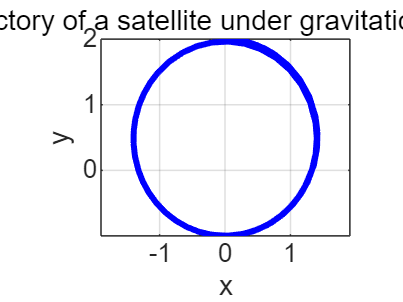

clc;
clear;

% 定义常量
G = 1;         % 引力常数 g = 1
m2 = 3;        % 大物体的质量 m2 = 3

% 定义微分方程组
odefun = @(t, Y) [Y(2);                                    % x' = vx
                 -G * m2 * Y(1) / (Y(1)^2 + Y(3)^2)^1.5;   % vx' = -G * m2 * x / r^3
                  Y(4);                                    % y' = vy
                 -G * m2 * Y(3) / (Y(1)^2 + Y(3)^2)^1.5];  % vy' = -G * m2 * y / r^3

% 时间区间
tspan = [0 10];

% 初始条件 [x(0), vx(0), y(0), vy(0)]
% 假设初始速度 vx(0) = 1, vy(0) = 0
y0 = [0; 1; 2; 0];   % x(0) = 0, y(0) = 2, vx(0) = 1, vy(0) = 0

% 使用 ode45 求解
[t, Y] = ode45(odefun, tspan, y0);

% 绘制轨迹 x 对 y
plot(Y(:,1), Y(:,3), 'b', 'LineWidth', 2);
xlabel('x');
ylabel('y');
title('Trajectory of a satellite under gravitational force');
grid on;
axis equal;